clear all
close all
clc
set(gcf,'Visible','on')
% syms m p w0

% f = logspace(0,6,1000);

% H = 1./(1+2*m*(p/w0)+(p.^2/w0^2));

m = 0.2;
w0 = 2*pi*1e3;
% p = 1i*2*pi.*f;


% H = subs(H);
% G = 20.*log10(abs(H));
% 
% subplot(2,1,1)
% semilogx(f,G);
% title("Diagramme de Bode")
% 
% subplot(2,1,2)
% semilogx(f,angle(H));
% title("Argument")


syms t p

fs = 1001;

Imp = dirac(t);
Ech = heaviside(t);
Sin = cos(2*pi*fs.*t)*Ech;

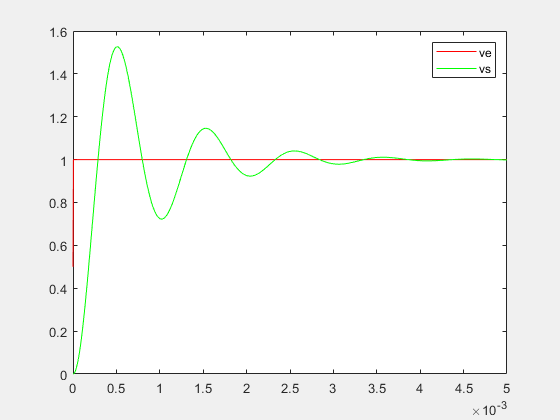

ve = Ech;

VE = laplace(ve,t,p);
H = 1./(1+2*m*(p/w0)+(p/w0)^2);
vs = ilaplace(H*VE,p,t);

t = linspace(0,5e-3,1000);

ve = subs(ve);
vs = subs(vs);


plot(t, ve,'r')
hold on
plot(t,vs,'g')
legend("ve","vs");

H = subs(H);

G = 20.*log10(abs(H))

$$G = \frac{20\,\log\left(\frac{1}{\left|\frac{p^{2}}{4000000\,\pi^{2}}+\frac{p}{5000\,\pi }+1\right|}\right)}{\log\left(10\right)}$$

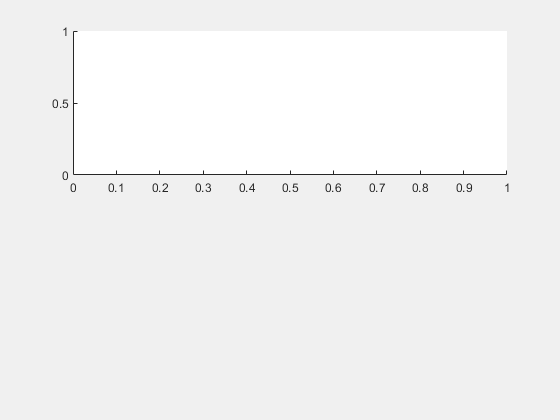


f = logspace(0,6,1000);

subplot(2,1,1)

semilogx(f,G);

Error using semilogx
Data must be numeric, datetime, duration or an array convertible to double.

title("Diagramme de Bode")

subplot(2,1,2)
semilogx(f,angle(H));
title("Argument")